# Calcium plot for Identifying stimuli specifc cell response

this code is to plot calcium imaging signals. What's required is a csv file containing intensity of ROIs. This code is modified based on CalciumPlot. Last edited on May 3 2025

#### Read Table and plot heatmap

stimuli = 'Results_4.csv'

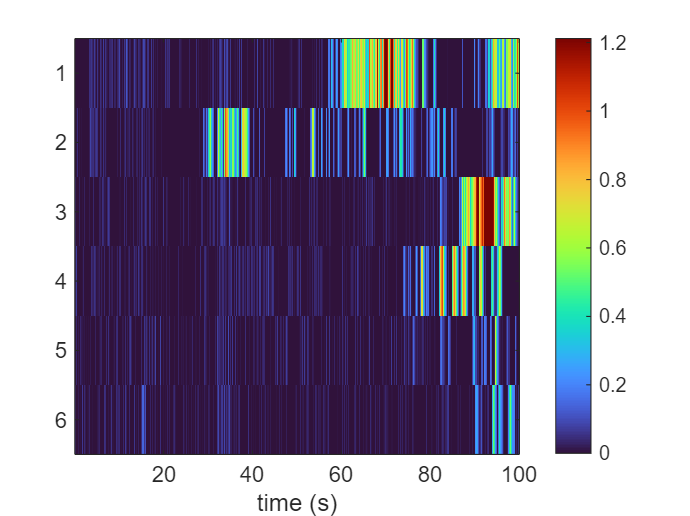

stimuli = 'Results_42.csv'

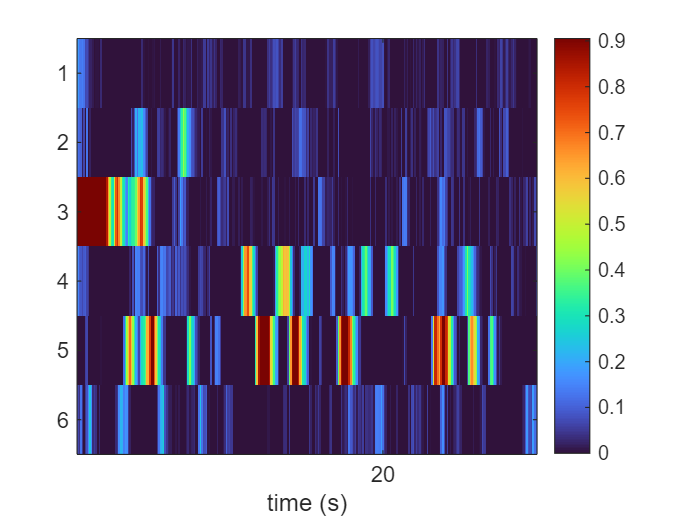

close all
clearvars -except path

[fileNames, pathName] = uigetfile('\\research.files.med.harvard.edu\neurobio\GintyLab\Xiao\Rig\calcium\*.csv', 'Select CSV files', 'MultiSelect', 'on');

datatable = struct([]);
fps = 10;
% Loop through each selected file and read it
for i = 1:length(fileNames)
    fullFileName = fullfile(pathName, fileNames{i});
    stimuli = fileNames{i}
    cur_data = readtable(fullFileName);      % or csvread/fullfile depending on format
    datatable(i).name = stimuli;
    datatable(i).Oridata = cur_data(:,startsWith(cur_data.Properties.VariableNames, 'Mean'));
    % if ~contains(stimuli,'pinch')
    %     datatable(i).framerate = 5; %Hz CHANGE FOR DIFFERENT SETTING
    %     fps = 5;
    % else
    %     datatable(i).framerate = 10;
    %     fps = 10;
    % end
    datatable(i).framerate = fps;
    normDeltaF = initialProcess(pathName, fileNames{i}, fps, 'bleach correction', 6, 0.975);
    NewnormDeltaF = normDeltaF(:,:) - mean(normDeltaF(1:100,:)); %baseline fixed to be 100 frames
    datatable(i).dataABC = NewnormDeltaF(:,:);%,27:end); %REMOVE SOME DUPLICATES
end

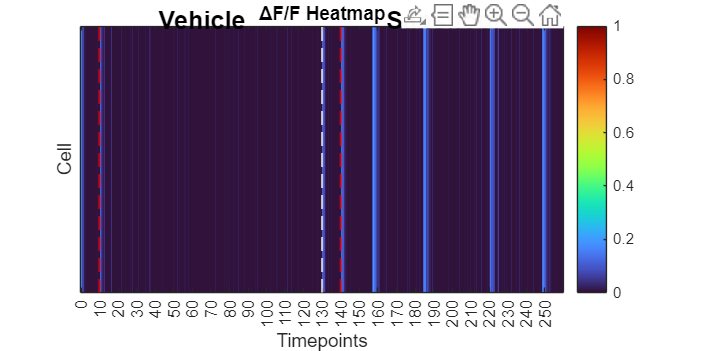

% re-order datatable
vehicle_data  = datatable(contains({datatable.name}, 'vehicle')).dataABC;
sanshool_data = datatable(contains({datatable.name}, 'Sanshool')).dataABC;
base = sanshool_data(1:100, :);
baseMu  = mean(base, 1, "omitnan");
baseStd = std(base, 0, 1, "omitnan");
nstd = 2;
thr = baseMu + nstd*baseStd;
post = sanshool_data(101:end, :);
isAbove = post > thr;                    
respDur = sum(isAbove, 1, "omitnan");
maxAll = max(sanshool_data, [], 1, "omitnan");
isResp = respDur > 0;
sortMat = [isResp(:), respDur(:), maxAll(:)];   % columns = keys
[~, sortIdx] = sortrows(sortMat, [-1 -2 -3]);

sans_sorted = sanshool_data(:, sortIdx);
veh_sorted  = vehicle_data(:,  sortIdx);
datatable(contains({datatable.name}, 'vehicle')).sortedABC = vehicle_data;
datatable(contains({datatable.name}, 'Sanshool')).sortedABC = sanshool_data;
all_data_sorted = [veh_sorted; sans_sorted];

stim_lengths = size(sanshool_data,1);
stim_boundaries = cumsum(stim_lengths);
stim_boundaries_2 = cumsum(stim_lengths)+100;
if size(all_data_sorted,2)>4
    MaxLimit = mean(all_data_sorted(end-4:end));
else
    MaxLimit = max(all_data_sorted);
end

if MaxLimit > 1.5 || MaxLimit < 0.2
    Limit = 1.5;
else
    Limit = MaxLimit;
end

Limit = 1;

% Plot heatmap
close all
fig1 = figure('Name','dF/F Heatmap','NumberTitle', 'off');
set(fig1, 'Units', 'pixels', 'Position', [100, 100, 1600, 800]);
nCells = size(all_data_sorted, 2);
nTime = size(all_data_sorted, 1);
imagesc(1:nTime, 1:nCells, all_data_sorted'); % rows = cells, columns = timepoints
colormap turbo;
colorbar;
caxis([0 Limit]);


totalSec = nTime / fps;
tickSec = 0:10:floor(totalSec);
tickFrames = tickSec * fps + 1;

xticks(tickFrames)
xticklabels(string(tickSec))
yticks(5:5:nCells);
xlabel('Timepoints');
ylabel('Cell');
title('ΔF/F Heatmap');
axis tight;

hold on;
for i = 1:numStim-1
    %xline(i * timelength + 0.5, 'w--', 'LineWidth', 1.2);
    xline(stim_boundaries(i), 'w--', 'LineWidth', 1.2);
    xline(stim_boundaries_2(i), 'r--', 'LineWidth', 1.2);
end
xline(100, 'r--','LineWidth', 1.2);
hold off;
ax = gca;
ax.Clipping = 'off';

text((size(vehicle_data,1)/2) / nTime, 1.02, 'Vehicle', ...
    'Units','normalized', ...
    'HorizontalAlignment','center', ...
    'FontSize',14, 'FontWeight','bold');

text((size(vehicle_data,1) + size(sanshool_data,1)/2) / nTime, 1.02, 'Sanshool', ...
    'Units','normalized', ...
    'HorizontalAlignment','center', ...
    'FontSize',14, 'FontWeight','bold');



heatmap_name = 'Heatmap Plot of cell responses.pdf';
heatmap_path = fullfile(pathName,heatmap_name);
exportgraphics(fig1, heatmap_path, 'ContentType', 'vector');

filename_output = strcat(extractBetween(pathName, 'calcium\', '\preprocess'), '_datatable.mat');
filename_output = filename_output{1};
save(fullfile(pathName, filename_output), 'datatable');


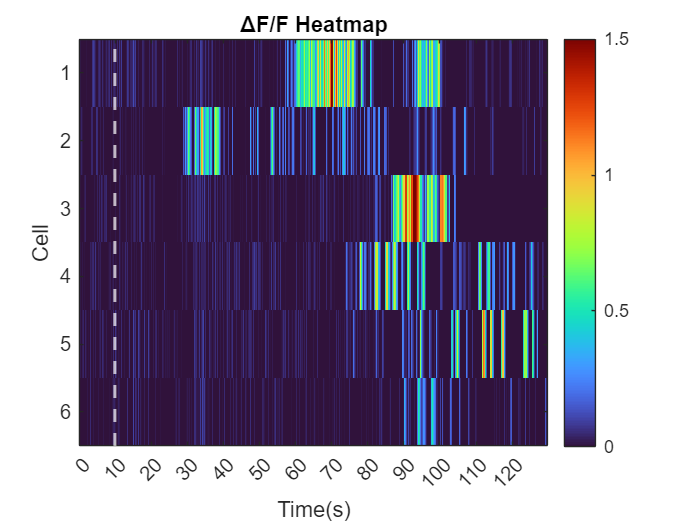

%
concatData.name = {datatable.name};
concatData.framerate = datatable(1).framerate;
concatData.Oridata = vertcat(datatable.Oridata);
concatData.dataABC = vertcat(datatable.dataABC);

baselineFrames = 100;
fps_baseline = 10;
fps_after = 5;

data_toplot = concatData.dataABC;
nCells = size(data_toplot, 2);
nTime = size(data_toplot, 1);

% Build time axis in seconds
timeSec = zeros(nTime, 1);
timeSec(1:baselineFrames) = (0:baselineFrames-1) / fps_baseline;
timeSec(baselineFrames+1:end) = ...
    baselineFrames / fps_baseline + ...
    (1:(nTime-baselineFrames)) / fps_after;

fig2 = figure();
imagesc(timeSec, 1:nCells, data_toplot');
hold on
xline(baselineFrames / fps_baseline, 'w--', 'LineWidth', 1.5);
hold off

    Limit = 1.5;
    totalSec = timeSec(end);
    tickSec = 0:60:floor(totalSec);
    xticks(tickSec);
    xticklabels(string(tickSec));
    tickFrames = tickSec * fps + 1;
    colormap turbo;
    colorbar;
    caxis([0 Limit]);
    xlabel('Time(s)');
    ylabel('Cell');
    title('ΔF/F Heatmap');
    axis tight;


heatmap_name = 'Heatmap Plot of cell responses_Sanshool.pdf';
heatmap_path = fullfile(pathName,heatmap_name);
exportgraphics(fig2, heatmap_path, 'ContentType', 'vector');

Stuff below are test codes used before

% Step 1: Get responses from stimulus 2 and 3
resp2 = max(datatable(2).dataABC', [], 2);   % Cells x 1 (max response per cell)
resp3 = max(datatable(3).dataABC', [], 2);   % Cells x 1

% Step 2: Lexicographic sorting (first by resp2, then by resp3)
[~, sortIdx] = sortrows([resp2 resp3], [-1 -1]);  % Descending for both

% Step 3: Concatenate all stimuli (transpose for cells x time)
numStim = numel(datatable);
data_per_stim = cell(1, numStim);
stim_lengths = zeros(1, numStim);
for i = 1:numStim
    data_per_stim{i} = datatable(i).dataABC';  % 63 x time
    stim_lengths(i) = size(data_per_stim{i}, 2);
end

% Step 4: Combine and sort
all_data = horzcat(data_per_stim{:});% 63 x total_time
sorted_data = all_data(:, sortIdx);         % Apply sort order

% Step 5: Plot
imagesc(sorted_data');
colormap(turbo);
colorbar;
caxis([0 1.5]);
axis xy;
axis tight;
xlabel('Time (frames)');
ylabel('Cell (sorted by Stim 2, then Stim 3)');
title('Heatmap: Cells Sorted by Stimulus 2, Then Stimulus 3');

% Step 6: Add stimulus boundaries
hold on;
stim_boundaries = cumsum(stim_lengths);
for i = 1:numStim-1
    xline(stim_boundaries(i)+0.5, 'w--', 'LineWidth', 1.2);
end

% Step 7: Add labels
xticks(stim_lengths/2 + [0 cumsum(stim_lengths(1:end-1))]);
xticklabels(erase({datatable.name}, '.csv'));
xtickangle(45);



png_name = 'Heatmap Plot of cell responses.png';
png_path = fullfile(pathName,png_name);
exportgraphics(fig(2), png_path, 'Resolution', 300);

#### If happy with the figure, save it

if (1)
    pathparts = strsplit(path,filesep);
    mouseID = pathparts{end-1}; clear pathparts
    name = [filename(1:end-4), '_', mouseID];
    t = title(name);
    set(t,'Interpreter','none')
    
    figureName = [path, name, '.jpg'];
    saveas(gcf,figureName)
    clear t
end

#### Save into structure called 'Data'

save the data into structure so it's easier to access in the future

% structName = [path, 'Data.mat'];
% if isfile(structName)
%     load(structName);
% else
%     Data = struct;
%     %data.info.mouseID = mouseID;
% end
% 
% if contains(filename,"frey")  % the fieldname can't start with number
%     filename = erase(filename, "von_frey");
%     filename = strcat('von_frey',filename);    
% end
% 
% Data.(filename(1:end-4)) =  normDeltaF;
% 
% 
% save(structName, 'Data');
% 
% clear structName

TableName = [path, 'Data.mat'];



#### Quatification and save the responsive ROIs into a structure

nStd = 3;%7; 
% the signal that is 'nStd' times of of standard deviation larger than noise (in baseline) is regarded as response 
% nStd can change depending on the sigal-to-noise ratio of imaging
% the baseline is the first 90 or 100 frames of the imaging averaged

%[digitROI, responseROI0] = quantify(normDeltaF, filename, nStd);

[digitROI, responseROI0] = quantify(nonOverlapData, fileNames{i}, nStd);

#### Plot traces of all responsive neurons

thresh = 0.1; 
spike0 = plotAllResponse(responseROI0, normDeltaF,path, filename, thresh, fps, ...
    "peakLabel", 1, 'NumFig', 60, 'save',0); 
% if "peakLabel" is 1, peaks will be labeled
% the spike0 contains the amplitude and timing of the peaks

#### Save the response information into two structure

% goodROI = [1, 2, 5, 7, 8, 10, 11, 20, 21, 24, 25, 26, 27 ]; badROI = setdiff(responseROI0, goodROI);
badROI = [];
[responseROI, responseIndex] = setdiff(responseROI0, badROI);
responseROI(2, :) = nStd; % nStd means the definition of response, stored in second line of responseROI
responseROI(3, 1:length(badROI)) = badROI;
spike = spike0(:, responseIndex,:);
% clear spike0 responseROI0

responseStructName = [path, 'responseROIstruct.mat'];
if isfile(responseStructName)
    load(responseStructName);
else
    responseROIstruct = struct;
end

responseROIstruct.(filename(1:end-4)) = responseROI;
% responseROIstruct.(filename(1:end-5)) = responseROI;

save(responseStructName, 'responseROIstruct');

spikeStructName = [path, 'spikeStruct.mat'];
if isfile(spikeStructName)
    load(spikeStructName);
else
    spikeStruct = struct;
end

spikeStruct.(filename(1:end-4)) = spike;
save(spikeStructName, 'spikeStruct');

#### Plot traces of certain neuron (optional)

If curious about what certain trace looks like, or what does bleach correction algorithm do to the trace


nCell = input('the neuron you are interesed in?  \n ');
figure,
subplot(211);
plot(normDeltaF(:,nCell)), title(['DeltaF/F of Cell ', num2str(nCell)]);
box off
% subplot(212),findpeaks(normDeltaF(:,nCell),'MinPeakProminence',thresh),title('Peaks');
[~, b, ~] = RobustDetrend(normDeltaF(:,nCell), 6, 0.975);
subplot(212), plot(b), 
title(['DeltaF/F of Cell ', num2str(nCell), ' bleach corrected']);
box off
